% Script to Analyze Level 1 Data Collection

clc;
close all;
clear all;

% Load data from rosbag - specify file name in 'rosbag(_____)'
% fullroom = rosbag('halfroom.bag');
% fullroom = rosbag('Lvl_1_Room_Map_1.bag'); % This one started at bottom of room
% 
% fullroom = rosbag('Lvl_1_Room_Map_2.bag'); % This one is complete garbage (half the room)
% fullroom = rosbag('Lvl_1_Room_Map_3.bag'); % Decent Results
% fullroom = rosbag('Lvl_1_Room_Map_4.bag'); % fairly clean results but missing a lot (lots of 5000's)
fullroom = rosbag('Lvl_1_Room_Map_5.bag');
% fullroom = rosbag('Lvl_1_Room_Map_6.bag');


% Display info (topics, timing, etc..)
rosbag info Lvl_1_Room_Map_1.bag;

Path:     /Users/jacob/Documents/MATLAB/EECE 5554 RSN/Final_Project/Lvl_1_Room_Map_1.bag
Version:  2.0
Duration: 54.4s
Start:    Apr 26 2023 14:40:16.27 (1682534416.27)
End:      Apr 26 2023 14:41:10.69 (1682534470.69)
Size:     1.4 MB
Messages: 2177
Types:    imu_driver/ImuEcho [20573da8e97f92f59f4f5b41391b644d]
Topics:   /fusion  2177 msgs  : imu_driver/ImuEcho




% Create bag selection object and read messages from slected topic
echos_data = select(fullroom, 'Topic', '/fusion');
echos = readMessages(echos_data, 'DataFormat', 'struct');

% populate desired arrays from structures

range = cellfun(@(m) double(m.Range), echos);
yaw = cellfun(@(m) double(m.Yaw), echos);

% adjust yaw initial offset - offset is in degrees

% yaw_init = 90; % Use for Map 1
yaw_init = -80; % Use for Maps 2-6

% negative yaw needed due to reverse z-axis
yaw = -yaw + deg2rad(yaw_init);

% Process imu_echo data to x_y coords from Sensor

% create blank cell arrays to hold data
echo_points_x = zeros(size(range));
echo_points_y = zeros(size(range));

% combine into one array
echo_points = [echo_points_x echo_points_y];

% get array size to control loop operation below
echo_size = size(range);
echo_end = echo_size(1,1);

% loop to populate each row of sensor xy coords (per Level 1 Model)
i = 1;

while i < echo_end+1

    if range(i) == 5000 % remove points that timed out
        echo_points(i,1) = 0;
        echo_points(i,2) = 0;

    elseif range(i) == 300 % remove points that saturated
        echo_points(i,1) = 0;
        echo_points(i,2) = 0;

    else % populate points with scaled values
    echo_points(i,1) = (range(i)/1000)*cos(yaw(i));
    echo_points(i,2) = (range(i)/1000)*sin(yaw(i));

    end

    i = i+1;

end

% find first valid point

i = 1;
first_nonzero = 1;

while i < echo_end+1

    if echo_points(i,1) == 0;
        i = i+1;
        continue

    else first_nonzero = i;
        break

    end

end

% Create Room Plot

room_points_x = [0 3.35 3.69 3.69 3.35 3.35 3.69 3.69 3.35 -1.72 -1.72 0 0];
room_points_y = [0 0 0 1.07 1.07 2.42 2.42 4.82 4.82 4.82 2.48 2.48 0];
room_points = [room_points_x; room_points_y];

% Transpose
room_points = room_points';

% sensor_origin = [1 2.75]; % use for Map 1
sensor_origin = [1.5 2.98]; % use for Maps 2-6


room_points = room_points-sensor_origin;

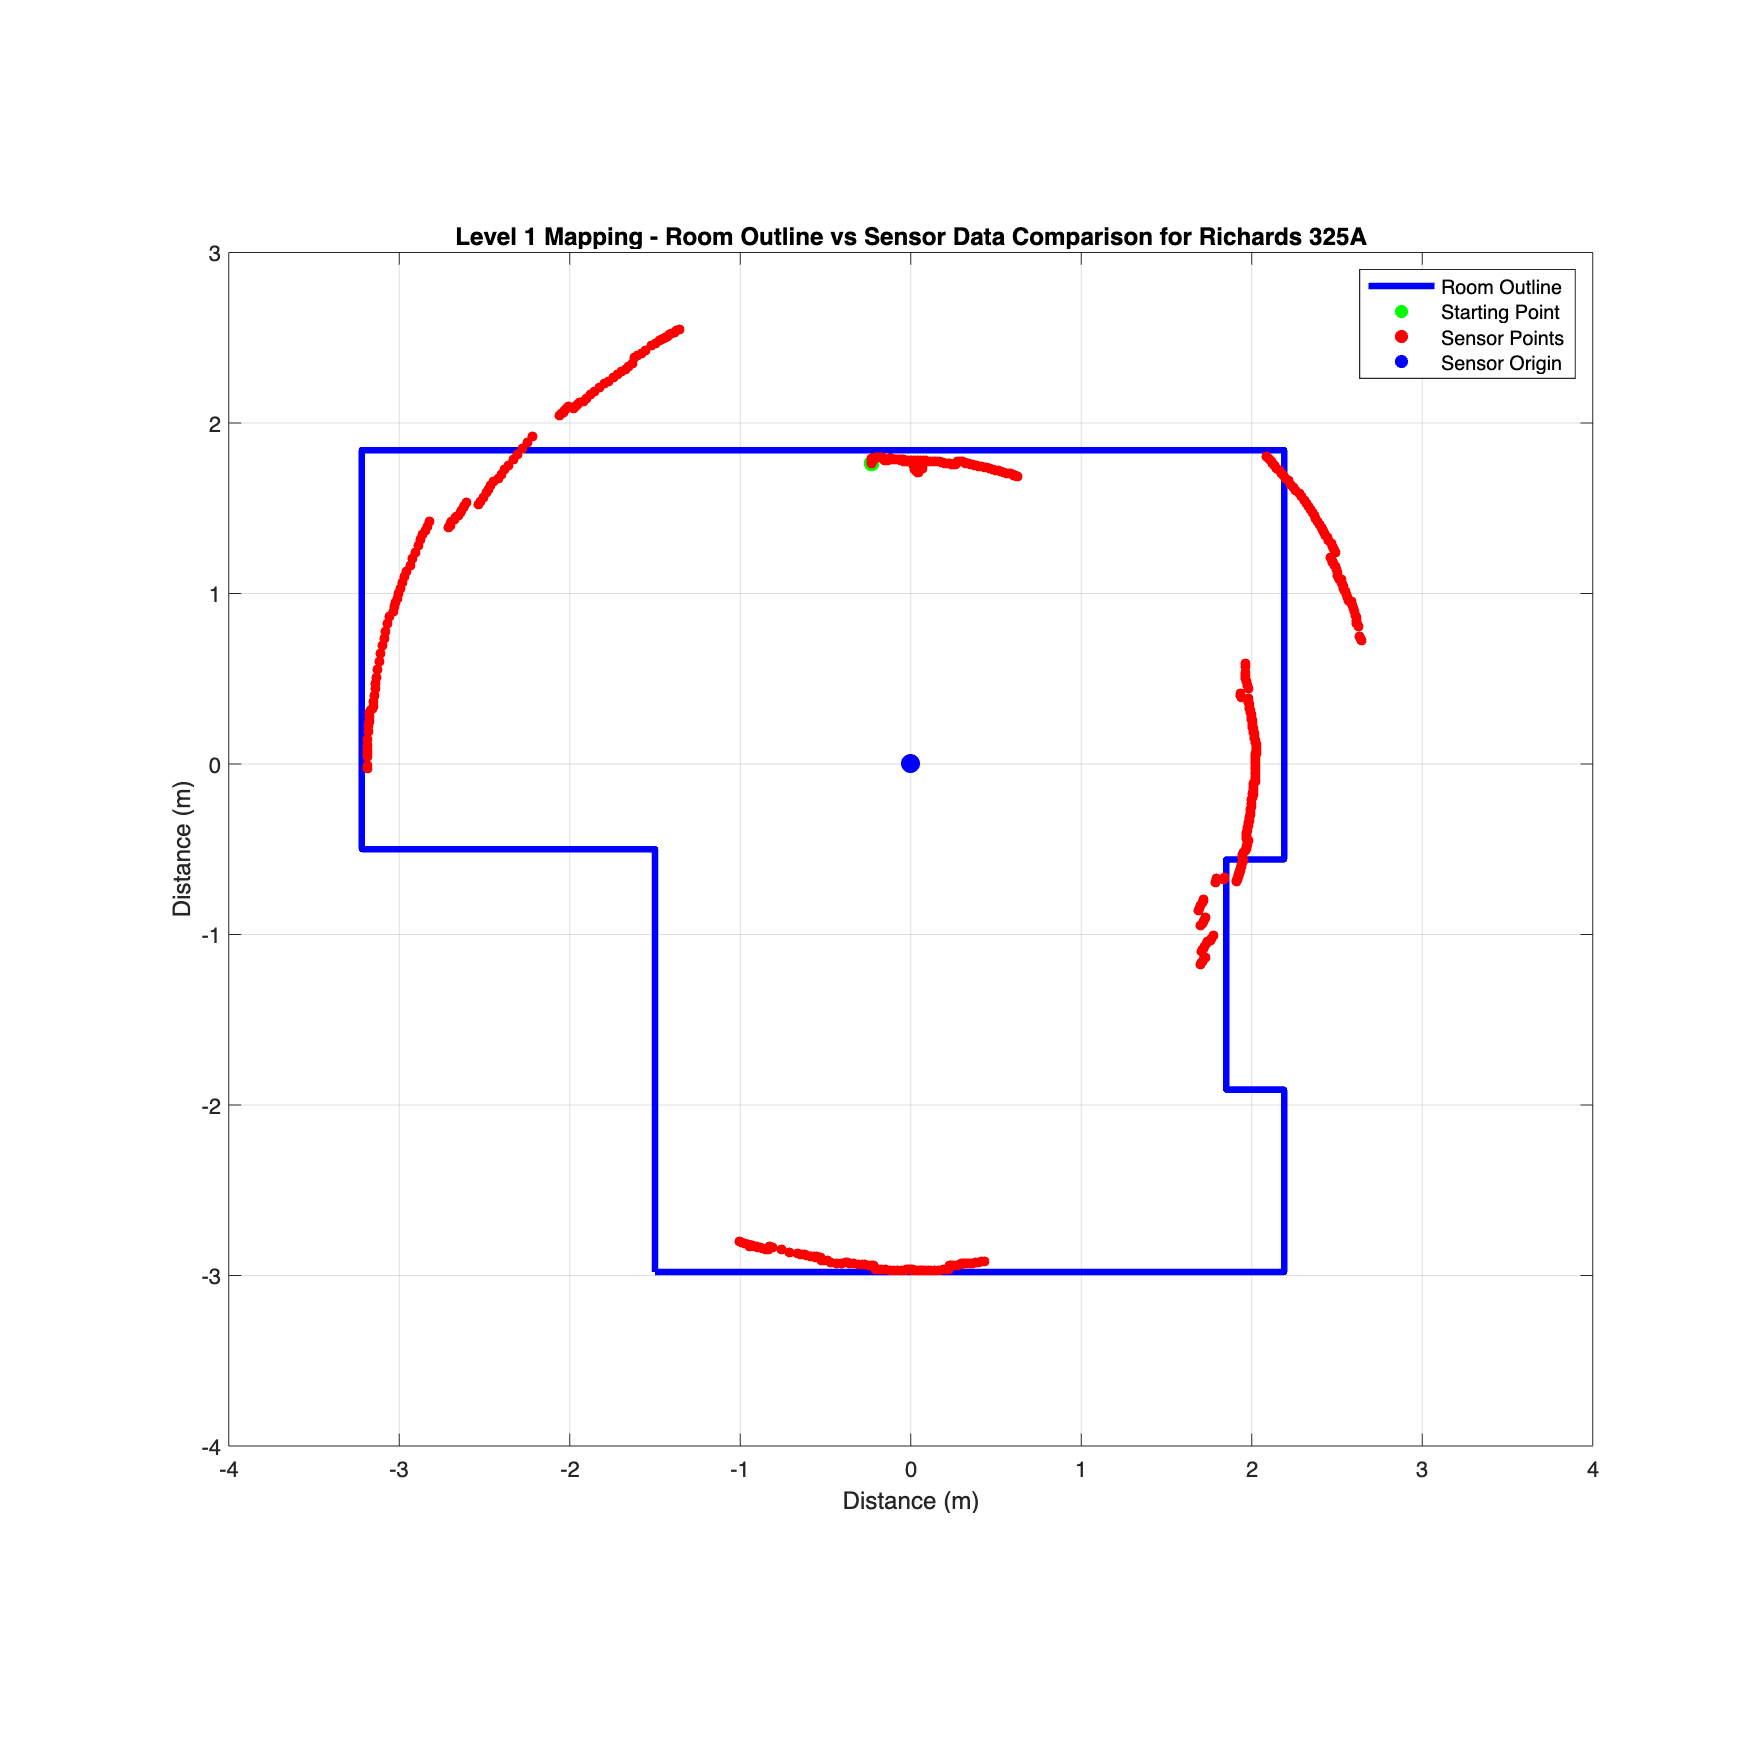

% Plot Room Layout vs. Sensor Data
% Sometimes you need to run this section again (a little glitchy)

figure('Name', 'Level 1 - Data Comparison', 'Position', [10 10 1000 1000]);

plot(room_points(:,1), room_points(:,2), 'b', 'LineWidth', 3); hold on; % room layout
scatter(echo_points(first_nonzero,1), echo_points(first_nonzero,2), 50, 'g', 'filled'); % plot first data point to help with orientation alignment
scatter(echo_points(:,1), echo_points(:,2), 20,'r', 'filled'); % sensor data
scatter(0,0,75,'b','filled'); % sensor origin
daspect([1 1 1]);
xlim([-4 4]); ylim([-4 3]);
xlabel('Distance (m)');
ylabel('Distance (m)');
legend('Room Outline', 'Starting Point', 'Sensor Points', 'Sensor Origin'); % create legend
title('Level 1 Mapping - Room Outline vs Sensor Data Comparison for Richards 325A'); % create title
grid on;

% pbaspect([1 1 1]); % fix aspect ratio to 1:1

% ylim([-8 8]); xlim([-8 8]); % set plot limits



% Analysis - Create Fit lines from Sensor Data

